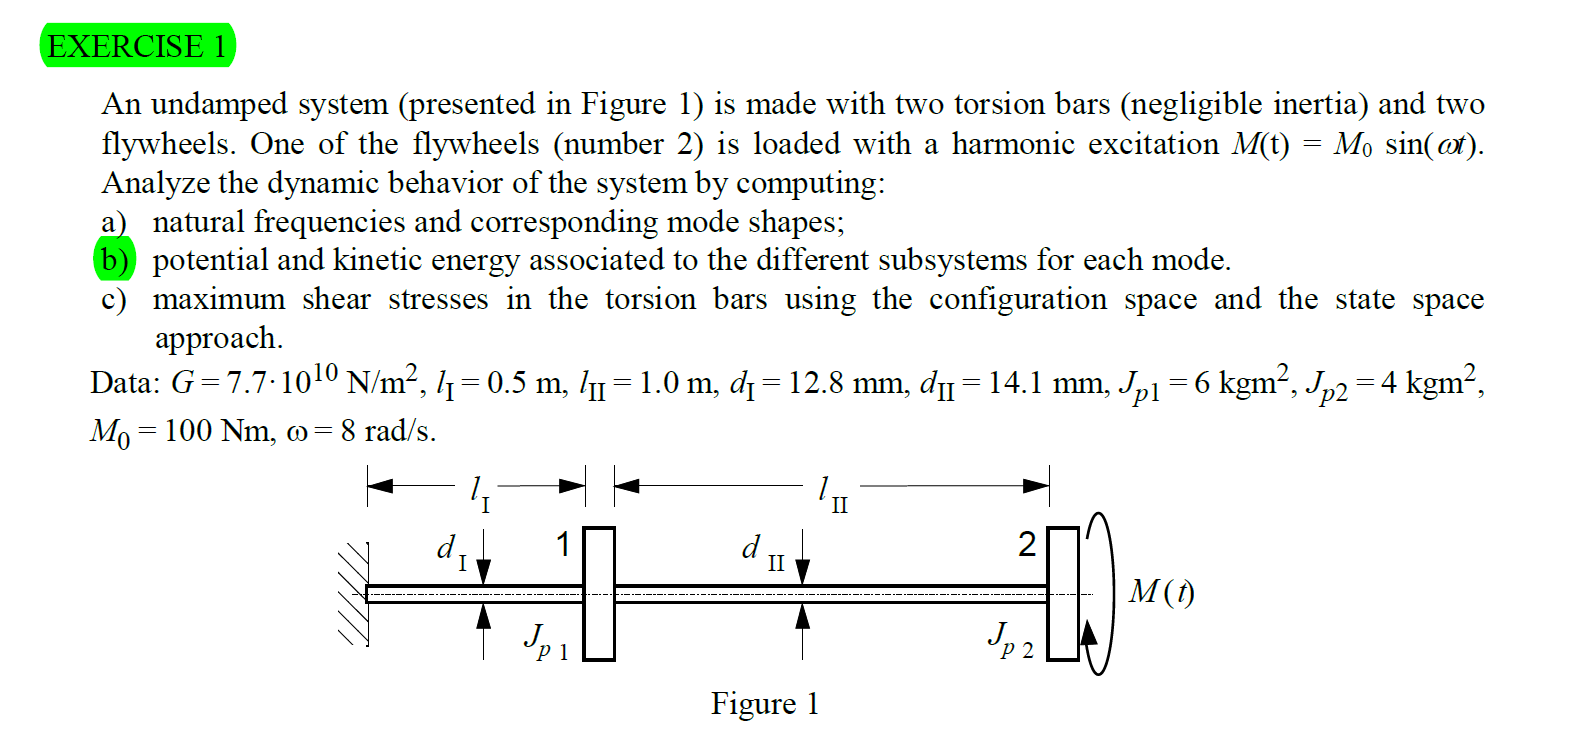

clear 
clc

G=7.7e10;
l1=.5;
l2=1;
d1=12.8e-3;
d2=14.1e-3;
Jp1=6;
Jp2=4;
M0=100;
wf=8;

Ip1=pi*d1^4/32;
Ip2=pi*d2^4/32;
k1=G*Ip1/l1;
k2=G*Ip2/l2;

M=[Jp1 0;0 Jp2];
K=[k1+k2 -k2;-k2 k2];
F=[0;M0];

%solve the eigenproblem det(K-w^2*M)=0, obtaining two values of w^2
[phi,w]=eig(K,M);

wn1=sqrt(w(1,1));
wn2=sqrt(w(2,2));

disp('1st torsional natural frequency [rad/s] = ')

1st torsional natural frequency [rad/s] = 


disp(wn1)

    5.6073



disp(' ');

disp('2nd torsional natural frequency [rad/s] = ')

2nd torsional natural frequency [rad/s] = 


disp(wn2)

   12.6765



disp(' ');


%put the value of wn1 (or wn2) in one of the two equations of the eigen
%problem to obtain phi1 (or phi2) and "normalize" it
phi1=phi(:,1)/max(abs(phi(:,1)));
phi2=phi(:,2)/max(abs(phi(:,2)));

disp('1st eigenvector = ')

1st eigenvector = 


disp(phi1)

   -0.5791
   -1.0000



disp(' ');

disp('2nd eigenvector = ')

2nd eigenvector = 


disp(phi2)

   -1.0000
    0.8686



disp(' ');


%CONFIGURATION SPACE

%Compute potential and kinetic energy associated to the different dofs for
%each mode (Txy=kinetic energy of dof y for mode x)
T11=(.5*Jp1*(wn1*phi(1,1))^2)/(.5*Jp1*(wn1*phi(1,1))^2+.5*Jp2*(wn1*phi(1,2))^2);
T12=(.5*Jp2*(wn1*phi(1,2))^2)/(.5*Jp1*(wn1*phi(1,1))^2+.5*Jp2*(wn1*phi(1,2))^2);
T21=(.5*Jp1*(wn2*phi(2,1))^2)/(.5*Jp1*(wn2*phi(2,1))^2+.5*Jp2*(wn2*phi(2,2))^2);
T22=(.5*Jp2*(wn2*phi(2,2))^2)/(.5*Jp1*(wn2*phi(2,1))^2+.5*Jp2*(wn2*phi(2,2))^2);

U11=(.5*k1*phi(1,1)^2)/(.5*k1*phi(1,1)^2+.5*k2*(phi(1,2)-phi(1,1))^2);
U12=(.5*k2*(phi(1,2)-phi(1,1))^2)/(.5*k1*phi(1,1)^2+.5*k2*(phi(1,2)-phi(1,1))^2);
U21=(.5*k1*phi(2,1)^2)/(.5*k1*phi(2,1)^2+.5*k2*(phi(2,2)-phi(2,1))^2);
U22=(.5*k2*(phi(2,2)-phi(2,1))^2)/(.5*k1*phi(2,1)^2+.5*k2*(phi(2,2)-phi(2,1))^2);

disp('1st mode: ')

1st mode: 


disp('Kinetic energy of dof1 [%] = ')

Kinetic energy of dof1 [%] = 


disp(T11*100)

   43.0031



disp('Kinetic energy of dof2 [%] = ')

Kinetic energy of dof2 [%] = 


disp(T12*100)

   56.9969



disp(' ');

disp('Potential energy of dof1 [%] = ')

Potential energy of dof1 [%] = 


disp(U11*100)

   88.9867



disp('Potential energy of dof2 [%] = ')

Potential energy of dof2 [%] = 


disp(U12*100)

   11.0133



disp(' ');

disp('2nd mode: ')

2nd mode: 


disp('Kinetic energy of dof1 [%] = ')

Kinetic energy of dof1 [%] = 


disp(T21*100)

   74.8882



disp('Kinetic energy of dof2 [%] = ')

Kinetic energy of dof2 [%] = 


disp(T22*100)

   25.1118



disp(' ');

disp('Potential energy of dof1 [%] = ')

Potential energy of dof1 [%] = 


disp(U21*100)

   31.7380



disp('Potential energy of dof2 [%] = ')

Potential energy of dof2 [%] = 


disp(U22*100)

   68.2620



disp(' ');


%Compute frequency responses for external forces, rotations and tensions
H=K-wf^2*M

H =   320.6360 -298.7907
 -298.7907   42.7907


x0=H\F;
tau1=x0(1)*k1*d1/(Ip1*2);
tau2=(x0(2)-x0(1))*k2*d2/(Ip2*2);

disp('Tangential tension on bar 1 [MPa] = ')

Tangential tension on bar 1 [MPa] = 


disp(abs(tau1)*10^-6)

  389.7632



disp('Tangential tension on bar 2 [MPa] = ')

Tangential tension on bar 2 [MPa] = 


disp(abs(tau2)*10^-6)

   15.6953




%MODAL APPROACH

%Compute modal mass, modal stiffness and modal forces
Jm=phi'*M*phi;
Km=phi'*K*phi;
Fm=phi'*F;

%Compute rotations
x0_m=(1/(wn1^2-wf^2)*phi(:,1)*phi(:,1)'+1/(wn2^2-wf^2)*phi(:,2)*phi(:,2)')*F;


%STATE SPACE
%dz=A*z+B*u
%y=C*x+D*u

A=[zeros(2) -inv(M)*K;eye(2) zeros(2)];
T=[0;1];
B=[inv(M);zeros(2)];
C=[0 0 k1*d1/(2*Ip1) 0;0 0 -k2*d2/(2*Ip2) k2*d2/(2*Ip2)];
D=zeros(2,2);


% sim('inspector.slx')

% [phi_s,lambda_s]=eig(A);
% phi_s1=real(phi_s(1:2,1)/max(abs(phi_s(1:2,1))));
% phi_s2=real(phi_s(1:2,3)/max(abs(phi_s(1:2,3))));
% wn_s1=abs(imag(lambda_s(1,1)));
% wn_s2=abs(imag(lambda_s(3,3)));
% 
% z0=[x0*wf;x0];
% tau_s=abs(C*z0)*10^-6;